 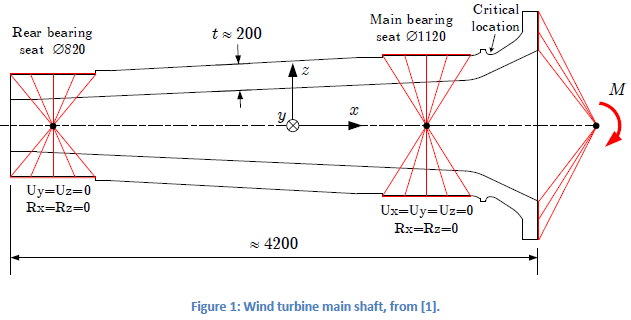

S_a_k = 176.4;
% n = K_t / K_f
E = 169*1e9;
nu = 0.27;
R_m = 400; %MPa 
R_z = 3.2; %m
% P_s = 97.7 procent
y_Mf = 1.265;

alpha_n = 0.32;
beta_n = 0.77;
%point 147431 (a)	204,2	2.521,83374023	-0,00000000	568,65960693
%point 13268 (b)	154,4	2.521,38549805	-0,00000000	563,48132324
x_1 = 568.65960693;
x_2 = 563.48132324;
S_1 = 204.2;
S_2 = 154.4;

S_max = S_a_k

S_max = 176.4000

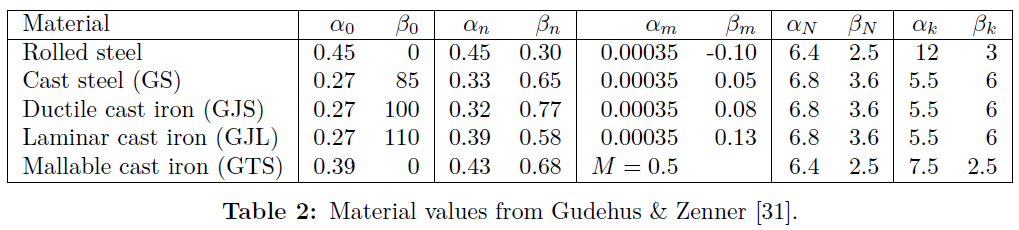


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$


X_grad = (S_1/S_max- S_2/S_max)/(x_1 - x_2)

X_grad = 0.0545

n = 1 + alpha_n * X_grad^beta_n

n = 1.0341

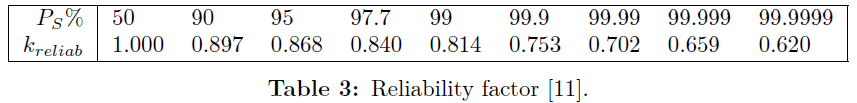

k_chill = 1.5;
k_reliab = 0.840;
k_surf = 1 - 0.22*log10(R_z)^0.64 * log10(R_m) + 0.45*log10(R_z)^0.53

k_surf = 0.9436


t_ref = 25;
t = 147;

alpha_t = 0.15;
k_size = (t_ref/t)^alpha_t

k_size = 0.7666

N_D = 1e6;
N_end = 1e9;
m1 = 5;
m2 = 2*m1 - 1

m2 = 9

alpha_0 = 0.27;
beta_0 = 100;

S_RD_mat = alpha_0 * R_m + beta_0

S_RD_mat = 208


S_RDk = k_size * k_surf * k_reliab * k_chill * n * S_RD_mat

S_RDk = 196.0437


% S_end = 

S_1s = [R_m,S_RDk]

S_1s =   400.0000  196.0437


N_1s = [0,N_D]

N_1s =            0     1000000


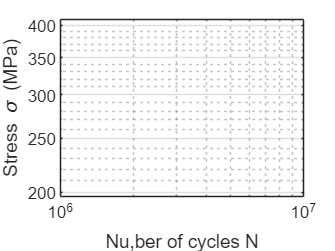


loglog(N_1s, S_1s)
hold on
xlabel('Nu,ber of cycles N')
ylabel('Stress \sigma (MPa)')
ylim([0,R_m+10])
xlim([0,1e7])
grid("on")

hold off


% S_2s = [S_RDk, S_end]
% N_2s = [N_D, N_end]